clear all;
close all;
clc

## 1. Problem description

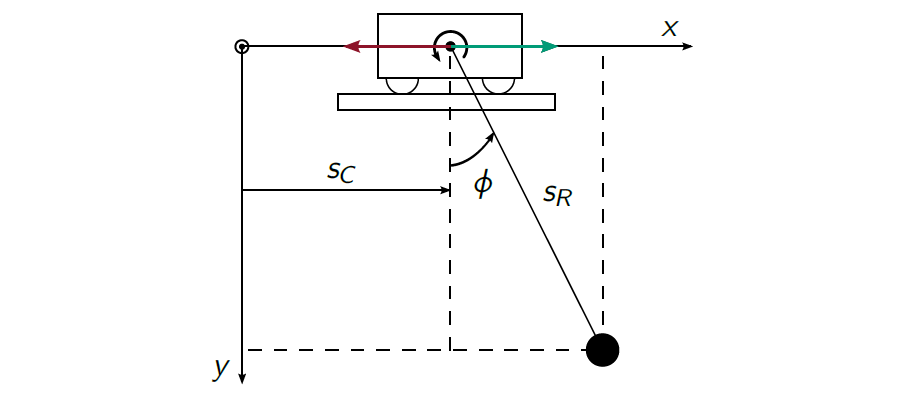

Consider the simplified 2D crane model shown above. The state and input vectors are


$$\mathbf{x}
=
\left[\begin{array}{c}
s_C &
\dot{s}_C &
s_R &
\dot{s}_R &
\varphi &
\dot{\varphi}
\end{array}\right]^T, \\
\mathbf{u}
=
\left[\begin{array}{c}
\ddot{s}_C &
\ddot{s}_R
\end{array}\right]^T,$$


where $s_C$ is the trolly positon, $s_R$ is the rope length and $\phi$ is the load angle.

The nonlinear dynamics are 


$$\dot{\mathbf{x}}
=
\mathbf{f}(\mathbf{x},\mathbf{u})
=
\left[\begin{array}{c}
x_2 \\
u_1 \\
x_4 \\
u_2 \\
x_6 \\
-\frac{2x_4x_6+u_1\cos(x_5)+g\sin(x_5)}{x_3}
\end{array}\right].$$


The load is moved to the desired state by solving


$$\min_{\mathbf{u}(.)} \quad J(\mathbf{u}) = \int_0^{T_h} (\mathbf{x}(\tau) - \mathbf{x}_{\text{des}})^T \, \mathbf{Q} \, (\mathbf{x}(\tau) - \mathbf{x}_{\text{des}}) + (\mathbf{u}(\tau) -  \mathbf{u}_{\text{des}})^T \, \mathbf{R} \, (\mathbf{u}(\tau) - \mathbf{u}_{\text{des}}) \, d\tau \\
\text{s.t.} \quad \dot{\mathbf{x}} = \mathbf{f}(\mathbf{x}, \mathbf{u}), \quad  \mathbf{x}(0) = \mathbf{x}_0 \\
\qquad \mathbf{u} \in [\mathbf{u}^-, \mathbf{u}^+], \\
\qquad h(\mathbf{x}) \leq 0.$$


As an exmple, consider a parabolic path constraint. The load position is


$$s_1(\mathbf{x}) = x_1 + x3 \, \sin(x_5), \quad s_s(\mathbf{x}) = -x_3 \, \cos(x_5).$$


For the boundary $s_2 =-a\;s_1^2 -b$, the load must remain abouve the parabola. Hence, 


$$h(\mathbf{x}) = x_3 \, \cos(x_5) - a\, (x_1 + x_3 \, \sin(x_5))^2  - b  \leq 0.$$


### Task

Using the MATLAB Symbolic Math Toolbox, define the system dynamics and staeg cost, and repectively compute the partial derivatives required for the GRAMPC implementation:


$$\frac{\partial \mathbf{f}}{\partial \mathbf{x}}, \quad
\frac{\partial \mathbf{f}}{\partial \mathbf{u}}, \quad
\frac{\partial \ell}{\partial \mathbf{x}}, \quad
\frac{\partial \ell}{\partial \mathbf{u}}, \quad
\frac{\partial h}{\partial \mathbf{x}}, \quad
\frac{\partial h}{\partial \mathbf{u}}. \quad$$


% Dimensions
nx = 6;
nu = 2;

% Symbolic variables
syms x [nx 1] real
syms u [nu 1] real
syms g real


% Dynamics
f = [
    x(2);
    u(1);
    x(4);
    u(2);
    x(6);
   -(g*sin(x(5)) + u(1)*cos(x(5)) + 2*x(4)*x(6))/x(3)
]

$$f = \left(\begin{array}{c} x_{2}\\ u_{1}\\ x_{4}\\ u_{2}\\ x_{6}\\ -\frac{2\,x_{4}\,x_{6}+u_{1}\,\cos\left(x_{5}\right)+g\,\sin\left(x_{5}\right)}{x_{3}} \end{array}\right)$$

%% Cost
syms xdes [nx 1] real
syms udes [nu 1] real

syms q [1 nx] real
syms r [1 nu] real

Q = diag(q);
R = diag(r);

l = (x - xdes).' * Q * (x - xdes) ...
  + (u - udes).' * R * (u - udes);

l = simplify(l)

$$l = r_{1}\,{\left(u_{1}-{\mathrm{udes}}_{1}\right)}^{2}+r_{2}\,{\left(u_{2}-{\mathrm{udes}}_{2}\right)}^{2}+q_{1}\,{\left(x_{1}-{\mathrm{xdes}}_{1}\right)}^{2}+q_{2}\,{\left(x_{2}-{\mathrm{xdes}}_{2}\right)}^{2}+q_{3}\,{\left(x_{3}-{\mathrm{xdes}}_{3}\right)}^{2}+q_{4}\,{\left(x_{4}-{\mathrm{xdes}}_{4}\right)}^{2}+q_{5}\,{\left(x_{5}-{\mathrm{xdes}}_{5}\right)}^{2}+q_{6}\,{\left(x_{6}-{\mathrm{xdes}}_{6}\right)}^{2}$$

%% Constraints
syms a b real
syms x6min x6max real

s1 = x(1) + sin(x(5))*x(3);

h_obs = cos(x(5))*x(3) ...
      - a*s1^2 ...
      - b;

h = [
    h_obs;
    x(6) - x6max;
    x6min - x(6)
]

$$h = \left(\begin{array}{c} x_{3}\,\cos\left(x_{5}\right)-b-a\,{\left(x_{1}+x_{3}\,\sin\left(x_{5}\right)\right)}^{2}\\ x_{6}-\mathrm{x6max}\\ \mathrm{x6min}-x_{6} \end{array}\right)$$

%% Jacobians
dfdx = simplify(jacobian(f, x))

$$dfdx = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & \frac{2\,x_{4}\,x_{6}+u_{1}\,\cos\left(x_{5}\right)+g\,\sin\left(x_{5}\right)}{{x_{3}}^{2}} & -\frac{2\,x_{6}}{x_{3}} & -\frac{g\,\cos\left(x_{5}\right)-u_{1}\,\sin\left(x_{5}\right)}{x_{3}} & -\frac{2\,x_{4}}{x_{3}} \end{array}\right)$$

dfdu = simplify(jacobian(f, u))

$$dfdu = \left(\begin{array}{cc} 0 & 0\\ 1 & 0\\ 0 & 0\\ 0 & 1\\ 0 & 0\\ -\frac{\cos\left(x_{5}\right)}{x_{3}} & 0 \end{array}\right)$$

dldx = simplify(jacobian(l, x).')

$$dldx = \left(\begin{array}{c} q_{1}\,\left(2\,x_{1}-2\,{\mathrm{xdes}}_{1}\right)\\ q_{2}\,\left(2\,x_{2}-2\,{\mathrm{xdes}}_{2}\right)\\ q_{3}\,\left(2\,x_{3}-2\,{\mathrm{xdes}}_{3}\right)\\ q_{4}\,\left(2\,x_{4}-2\,{\mathrm{xdes}}_{4}\right)\\ q_{5}\,\left(2\,x_{5}-2\,{\mathrm{xdes}}_{5}\right)\\ q_{6}\,\left(2\,x_{6}-2\,{\mathrm{xdes}}_{6}\right) \end{array}\right)$$

dldu = simplify(jacobian(l, u).')

$$dldu = \left(\begin{array}{c} r_{1}\,\left(2\,u_{1}-2\,{\mathrm{udes}}_{1}\right)\\ r_{2}\,\left(2\,u_{2}-2\,{\mathrm{udes}}_{2}\right) \end{array}\right)$$

dhdx = simplify(jacobian(h, x))

$$dhdx = \left(\begin{array}{cccccc} -a\,\left(2\,x_{1}+2\,x_{3}\,\sin\left(x_{5}\right)\right) & 0 & \cos\left(x_{5}\right)-2\,a\,\sin\left(x_{5}\right)\,\left(x_{1}+x_{3}\,\sin\left(x_{5}\right)\right) & 0 & -x_{3}\,\sin\left(x_{5}\right)-2\,a\,x_{3}\,\cos\left(x_{5}\right)\,\left(x_{1}+x_{3}\,\sin\left(x_{5}\right)\right) & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & -1 \end{array}\right)$$

dhdu = simplify(jacobian(h, u))

$$dhdu = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

## 2. Simulation study

Run the provided MATLAB app and simulate different constraint scenarios using default parameters.

Then vary selected parameters , such as the prediction horizon, angle and angular-velocity limits or obstacle geometry and compare the resulting crane motion.

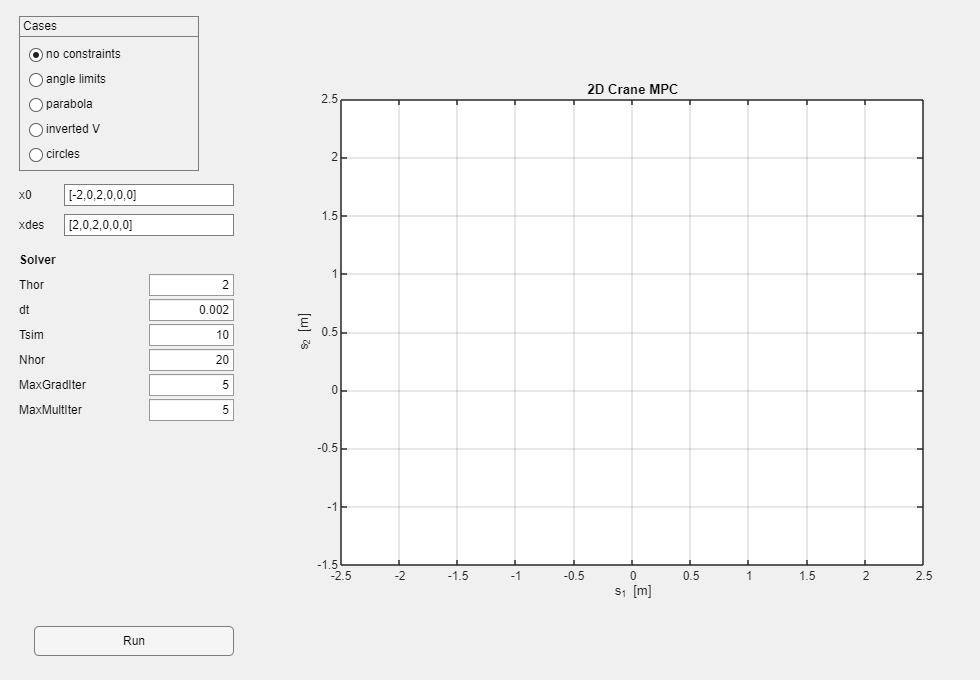

Crane2D_app_v7;